clc
clear
close all
set(0,'defaultAxesFontSize', 12)
set(0, 'DefaultLineLineWidth', 2);

## Load Data

data = load('Data/ex2data1.txt');
X = data(:, [1, 2]); % regressors matrix
y = data(:, 3); % output

## Part 1: Plotting

fprintf(['Plotting data with + indicating (y = 1) examples and o ' ...
    'indicating (y = 0) examples.\n']);

Plotting data with + indicating (y = 1) examples and o indicating (y = 0) examples.


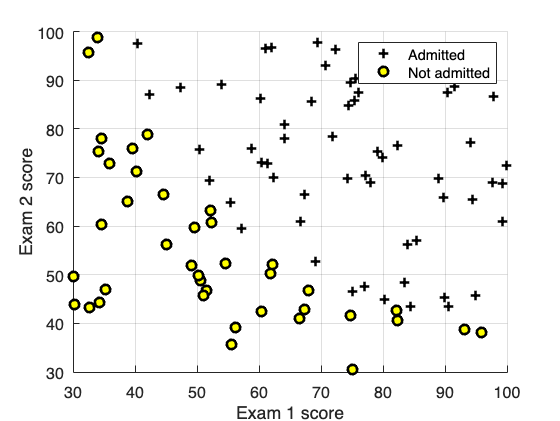


plotData(X, y);
hold on;
xlabel('Exam 1 score')
ylabel('Exam 2 score')
grid on
legend('Admitted', 'Not admitted')

## Part 2: Compute Cost and Gradient 

%  Setup the data matrix appropriately, and add ones for the intercept term
[N, d] = size(X);

X = [ones(N, 1) X]; % Add intercept term

initial_theta = zeros(d + 1, 1); % Initialize fitting parameters

% Compute and display initial cost and gradient
[cost, grad] = costFunction(initial_theta, X, y);


fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147


fprintf('Gradient at initial theta (zeros): \n');

Gradient at initial theta (zeros): 


fprintf(' %f \n', grad);

 -0.100000 
 -12.009217 
 -11.262842 


## Part 3: Optimizing using fminunc 

%  Set options for fminunc
options = optimset('GradObj', 'on', 'MaxIter', 400);

%  Run fminunc to obtain the optimal theta
%  This function will return theta and the cost
initial_theta = zeros(d + 1, 1);
[theta, cost] = fminunc(@(t)(costFunction(t, X, y)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



% Print theta to screen
fprintf('Cost at theta found by fminunc: %f\n', cost);

Cost at theta found by fminunc: 0.203498


fprintf('theta: \n');

theta: 


fprintf(' %f \n', theta);

 -25.161343 
 0.206232 
 0.201472 


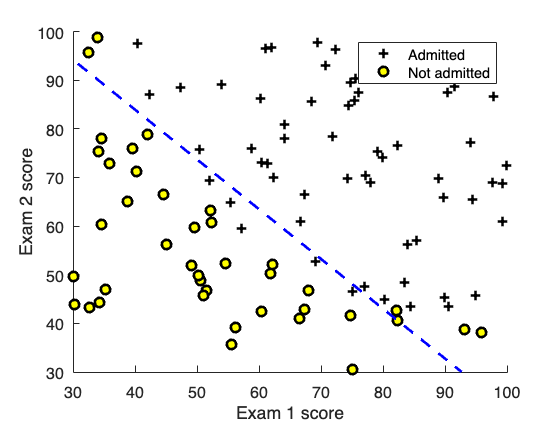


% Plot Boundary
plotDecisionBoundary(theta, X, y, []);

% Put some labels
hold on;
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')

% Specified in plot order
legend('Admitted', 'Not admitted')
hold off;

##  Part 4: Predict and Accuracies 

%  Predict probability for a student with score 45 on exam 1
%  and score 85 on exam 2

prob = sigmoid([1 45 85] * theta);
fprintf(['For a student with scores 45 and 85, we predict an admission ' ...
    'probability of %f\n\n'], prob);

For a student with scores 45 and 85, we predict an admission probability of 0.776291




% Compute accuracy on our training set
p = predict(theta, X);

ans =    -2.3011  -10.0717   -3.0807    4.6390    6.3175   -4.5176    6.8851   -0.3095    8.1454    1.0221    2.3097   -3.5255    7.2219    8.8314   -1.6880    3.9420   -0.2912   -1.7441    8.1335    0.2993   -2.6364    6.5896   -4.8964   -9.1988    4.8051    1.7748    0.4067    1.8590   -2.2848   -4.0677    2.1657    3.9461   -1.6966   -0.4392   -2.5249   -3.3742    1.7525    4.3747   -1.3616   -2.9533    3.4865   -5.0903    7.5262    0.0091   -5.4017   -1.8402    4.9536   12.4755    7.1363   11.5921



fprintf('Train Accuracy: %f\n', sum(mean(p == y) * 100));

Train Accuracy: 40.000000
